# **A neuroimaging biomarker for sustained experimental and clinical pain**

## **Chapter 1. Applying ToPS onto an example participant's fMRI data**

### Introduction

Welcome! In this tutorial, we will walk you through how to apply Tonic Pain Signature (ToPS) onto an example participant's fMRI data to predict sustained pain intensity of individuals.

#### Pipeline Summary

- Extract mean ROI timeseries from fully preprocessed fMRI data using 279-region Brainnetome atlas.

- Calculate dynamic functional connectivity using Dynamic Conditional Correlation (DCC) method.

- Apply ToPS onto the DCC data and compare the calculated ToPS scores and actual pain ratings.

#### Requirements

- **ToPS**: The model will be shared via a Material Transfer Agreement (only for the scientific research purpose). After downloading the model file ("ToPS_weight.mat"), please place it within the "tops/model/" folder (path: "tops/model/ToPS_weight.mat").

- **Data**: The tutorial data are available at the following [figshare](https://figshare.com/articles/dataset/data_zip/13082519) page. After downloading the compressed data file ("data.zip"), uncompress it and place the "data" folder within the "tops" folder (path: "tops/data").

#### Reference

- Jae-Joong Lee, Hong Ji Kim, Marta Ceko, Bo-yong Park, Soo Ahn Lee, Hyunjin Park, Mathieu Roy, Seong-Gi Kim, Tor D. Wager*, Choong-Wan Woo*, A neuroimaging biomarker for sustained experimental and clinical pain, 2020, *Nature Medicine* (*co-corresponding authors)

### Step 1. Extract mean ROI timeseries from fully preprocessed fMRI data using 279-region Brainnetome atlas.

ToPS predicts sustained pain intensity based on whole-brain functional connectivity data. The brain parcellation used for constructing functional connectivity is a 279-region Brainnetome atlas (path: "tops/data/atlas/Fan_et_al_atlas_r279_MNI_3mm.nii"). In this first step, we will use the Brainnetome atlas to extract mean ROI timeseries from fully-preprocessed fMRI data.

The fully-preprocessed fMRI data used in this example is one participant of Study 3 in our reference paper (Lee et al., 2020), and provided through [figshare](https://figshare.com/articles/dataset/data_zip/13082519) page as described above. This fMRI data was (i) motion-corrected, (ii) distortion-corrected, (iii) normalized to MNI 3mm^3 space through EPI-to-T1-to-MNI projection, (iv) denoised by regressing 24-motion parameters, signal outliers, finger movement-related signals, (v) filtered with 0.1Hz low-pass-filter (for details, please see our reference paper). However, any fMRI data preprocessed with the custom pipeline comparable to ours can be used for this tutorial as well.

We will first define the base directory, where the "tops" folder is located. The path can be variable, so please check where you located the downloaded "tops" repository.

basedir = '/Users/jaejoonglee/github/cocoanlab/tops'; % Check this path!

For conveinence and visibility, we prepared some custom functions in the "tops/functions" folder. Most of these functions were copied (and edited a bit) from [CanlabCore](https://github.com/canlab/CanlabCore) and [cocoanCORE](https://github.com/cocoanlab/cocoanCORE). Let's add these functions into our MATLAB path for future use.

addpath(genpath(fullfile(basedir, 'functions')));

Next, we have to specify where are the fMRI images to be processed. These images are located in "tops/data/example_participant/fMRI" data. If you want to use your own fMRI data for this tutorial, please change the path to where your data are located. Here, we will use one participant's fMRI data from Study 3. Although there are four different experimental conditions in Study 3, we will use only the "capsaicin" and "control" conditions in this tutorial.

fmri_imgs{1} = fullfile(basedir, 'data/example_participant/fMRI/example_preprocessed_fMRI_task-REST.nii.gz');
fmri_imgs{2} = fullfile(basedir, 'data/example_participant/fMRI/example_preprocessed_fMRI_task-CAPS.nii.gz');

Counting the number of runs.

n_run = numel(fmri_imgs);

Also, let's specify the path to our brain atlas. Note that this file should not be changed, because the ToPS was built based on this 279-region brain atlas.

atlas_img = fullfile(basedir, 'data/atlas/Fan_et_al_atlas_r279_MNI_3mm.nii');

We will extract mean ROI timeseries using a FSL command, "fslmeants". Since Matlab sometimes does not support inheritance of environmental variables from system, we will set environmental variables every time we run system commands.

fsl_env_cmd = 'FSLDIR=/usr/local/fsl; . ${FSLDIR}/etc/fslconf/fsl.sh; PATH=${FSLDIR}/bin:${PATH};';

The output wil be saved into "tops/data/example_participant/ROI' directory.

roi_meants{1} = fullfile(basedir, 'data/example_participant/ROI/example_ROI_mean_timeseries_task-REST.mat');
roi_meants{2} = fullfile(basedir, 'data/example_participant/ROI/example_ROI_mean_timeseries_task-CAPS.mat');

For every run, let's run the "fslmeants" command.

for img_i = 1:n_run
    fsl_cmd = sprintf('fslmeants -v -i %s --label=%s -o %s', fmri_imgs{img_i}, atlas_img, roi_meants{img_i});
    fprintf('Running FSL command: [ %s ]\n', fsl_cmd);
    system([fsl_env_cmd ' ' fsl_cmd]);
end

Running FSL command: [ fslmeants -v -i /Users/jaejoonglee/github/cocoanlab/tops/data/example_participant/fMRI/example_preprocessed_fMRI_task-REST.nii.gz --label=/Users/jaejoonglee/github/cocoanlab/tops/data/atlas/Fan_et_al_atlas_r279_MNI_3mm.nii -o /Users/jaejoonglee/github/cocoanlab/tops/data/example_participant/ROI/example_ROI_mean_timeseries_task-REST.mat ]


label:: Size = (60,72,60,1)
label:: Dims = (3,3,3,0)
label:: ROI Size = (60,72,60,1)
label:: Minimum and maximum intensities are: 0 and 279
Number of voxels used = 199
Number of voxels used = 266
Number of voxels used = 273
Number of voxels used = 224
Number of voxels used = 225
Number of voxels used = 249
Number of voxels used = 192
Number of voxels used = 182
Number of voxels used = 218
Number of voxels used = 224
Number of voxels used = 205
Number of voxels used = 261
Number of voxels used = 295
Number of voxels used = 274
Number of voxels used = 289
Number of voxels used = 305
Number of voxels used = 240
Number of voxels used = 167
Number of voxels used = 231
Number of voxels used = 295
Number of voxels used = 280
Number of voxels used = 253
Number of voxels used = 281
Number of voxels used = 230
Number of voxels used = 190
Number of voxels used = 196
Number of voxels used = 234
Number of voxels used = 319
Number of voxels used = 86
Number of voxels used = 92
Number of voxels used 

Running FSL command: [ fslmeants -v -i /Users/jaejoonglee/github/cocoanlab/tops/data/example_participant/fMRI/example_preprocessed_fMRI_task-CAPS.nii.gz --label=/Users/jaejoonglee/github/cocoanlab/tops/data/atlas/Fan_et_al_atlas_r279_MNI_3mm.nii -o /Users/jaejoonglee/github/cocoanlab/tops/data/example_participant/ROI/example_ROI_mean_timeseries_task-CAPS.mat ]


label:: Size = (60,72,60,1)
label:: Dims = (3,3,3,0)
label:: ROI Size = (60,72,60,1)
label:: Minimum and maximum intensities are: 0 and 279
Number of voxels used = 199
Number of voxels used = 266
Number of voxels used = 273
Number of voxels used = 224
Number of voxels used = 225
Number of voxels used = 249
Number of voxels used = 192
Number of voxels used = 182
Number of voxels used = 218
Number of voxels used = 224
Number of voxels used = 205
Number of voxels used = 261
Number of voxels used = 295
Number of voxels used = 274
Number of voxels used = 289
Number of voxels used = 305
Number of voxels used = 240
Number of voxels used = 167
Number of voxels used = 231
Number of voxels used = 295
Number of voxels used = 280
Number of voxels used = 253
Number of voxels used = 281
Number of voxels used = 230
Number of voxels used = 190
Number of voxels used = 196
Number of voxels used = 234
Number of voxels used = 319
Number of voxels used = 86
Number of voxels used = 92
Number of voxels used 

Load the output.

for img_i = 1:n_run
    roi_meants_dat{img_i} = load(roi_meants{img_i}, '-ASCII');
end

### Step 2. Calculate dynamic functional connectivity using Dynamic Conditional Correlation (DCC) method.

Next, let's calculate whole-brain functional connectivity from the extracted mean ROI timeseries. Here we will use Dynamic Conditional Correlation (DCC) methods (Lindquist et al., 2014; [Github repository](https://github.com/canlab/Lindquist_Dynamic_Correlation)) for dynamic connectivity calculation.

DCC is based on generalized autoregressive conditional heteroscedastic (GARCH) and exponential weighted moving average (EWMA) models, and has shown to have better sensitivity and specificity in capturing dynamical changes in correlation compared to the conventional sliding window dynamic correlation method. For computational efficiency, we estimated parameters of the DCC model from the whole pairs of BOLD timeseries with the assumption that EWMA model parameters are consistent across whole connections.

You can use either "DCCsimple" function of the original DCC toolbox ([Github repository](https://github.com/canlab/Lindquist_Dynamic_Correlation)), or use custom in-house function "DCC_jj" that was included in the "tops/functions" directory. We recommend using "DCC_jj", which uses the same algorithm as "DCCsimple.m" but is more simplified version and and includes "whiten" option that apply ARMA(1,1) whitening to the ROI timeseries.

We will calculate DCC using "DCC_jj" function. This process takes roughly an hour per one fMRI image (containing 2,586 volumes, which are quite large), with Intel Xeon E5, 3GHz, single core CPU.

for img_i = 1:n_run
    fprintf('Working on DCC: Image %d ...\n', img_i);
    dfc_dat{img_i} = DCC_jj(roi_meants_dat{img_i}, 'simple', 'whiten');
end

Working on DCC: Image 1 ...


ARMA(1,1) on 279 variables: 00279
    done.


Working on DCC: Image 2 ...


ARMA(1,1) on 279 variables: 00279
    done.


These dynamic functional connectivity data will be divided and averaged into pre-defined numbers of time-bins. In this tutorial, we will try 5 bins as the original paper. Then, the 'binned-connectivity' data will be saved into "tops/data/example_participant/FC" directory.

n_bin = 5;
dfc_binned{1} = fullfile(basedir, 'data/example_participant/FC/example_dFC_binned_task-REST.mat');
dfc_binned{2} = fullfile(basedir, 'data/example_participant/FC/example_dFC_binned_task-CAPS.mat');

Temporal binning of dynamic functional connectivity data.

for img_i = 1:n_run
    dfc_binned_dat = zeros(size(dfc_dat{img_i},1), n_bin);
    for div_i = 1:n_bin
        div_range = ceil(size(dfc_dat{img_i},2) / n_bin * (div_i-1) + 1) : ceil(size(dfc_dat{img_i},2) / n_bin * div_i);
        dfc_binned_dat(:,div_i) = mean(dfc_dat{img_i}(:,div_range), 2);
    end
    save(dfc_binned{img_i}, 'dfc_binned_dat');
end

### Step 3. Apply ToPS onto the DCC data and compare the calculated ToPS scores and actual pain ratings.

Now we will calculate ToPS score by taking dot product between ToPS predictive weights and DCC data. Then, this ToPS score will be compared with actual pain ratings reported in MRI scanner.

First, let's load the ToPS.

load(fullfile(basedir, 'model/ToPS_weight.mat'), 'ToPS_w');

Calculate ToPS score by taking dot product between the ToPS and each DCC data.

for img_i = 1:n_run
    load(dfc_binned{img_i}, 'dfc_binned_dat');
    tops_score{img_i} = sum(dfc_binned_dat .* ToPS_w, 'omitnan')';
end

Load the actual pain ratings (if you have used your custom fMRI data for this tutorial, here you can load the matched pain rating files as well).

pain_rating{1} = fullfile(basedir, 'data/example_participant/pain_rating/example_pain_rating_task-REST.mat');
pain_rating{2} = fullfile(basedir, 'data/example_participant/pain_rating/example_pain_rating_task-CAPS.mat');

for img_i = 1:n_run
    load(pain_rating{img_i}, 'pain_rating_dat')
    pain_rating_all{img_i} = pain_rating_dat;
end

Now we have both ToPS scores and actual pain ratings. We will see how much they are related with each other by displaying temporal changes of them.

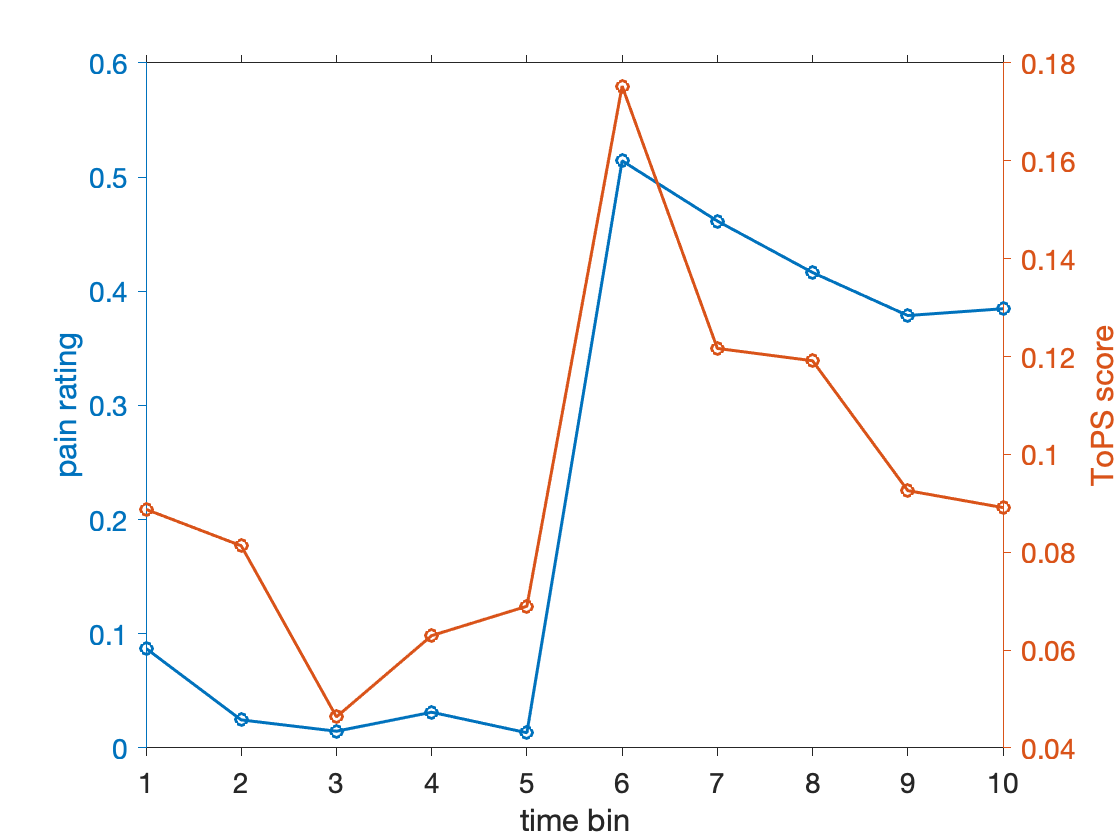

figure;
yyaxis left;
plot(cat(1, pain_rating_all{:}), '-o', 'linewidth', 1.5);
ylabel('pain rating');
yyaxis right;
plot(cat(1, tops_score{:}), '-o', 'linewidth', 1.5);
ylabel('ToPS score');
xlabel('time bin');
set(gca, 'tickdir', 'out', 'fontsize', 14);
set(gcf, 'color', 'w');

Can you see the substantial overlap between the two values?

### Summary

Well done! We have walked through how to apply ToPS onto a single fMRI data to calculate the signature scores and compare them with actual pain ratings. We know this is a relatively easy example, and usually the sample size to be tested is about tens or hundreds. In the next example livescript ("whole_participants_script.m"), we will apply and evaluate the ToPS onto multiple independent fMRI datasets, across tonic, clinical, and phasic pain. Thank you for your attention, and please contact us if you have any problem with following this tutorial.

Final edit: 2020. 11. 8

*Jae-Joong Lee* and *Choong-Wan Woo*.